# Converters

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

DC-to-DC converters (also known as choppers) are electronic devices that convert direct current (DC) electrical power from one voltage level to another. They are essential in various applications where the voltage supplied by the power source doesn't match the voltage required by the device. Unlike power inverters, which convert DC to alternating current (AC), DC-to-DC converters maintain the power in the same form but adjust its voltage level. These converters are crucial for the efficient operation of a wide range of electronic equipment, from small devices like mobile phones to large systems like electric vehicles and renewable energy installations. In this script, we will explore the theory and applications of converters in power electronics.

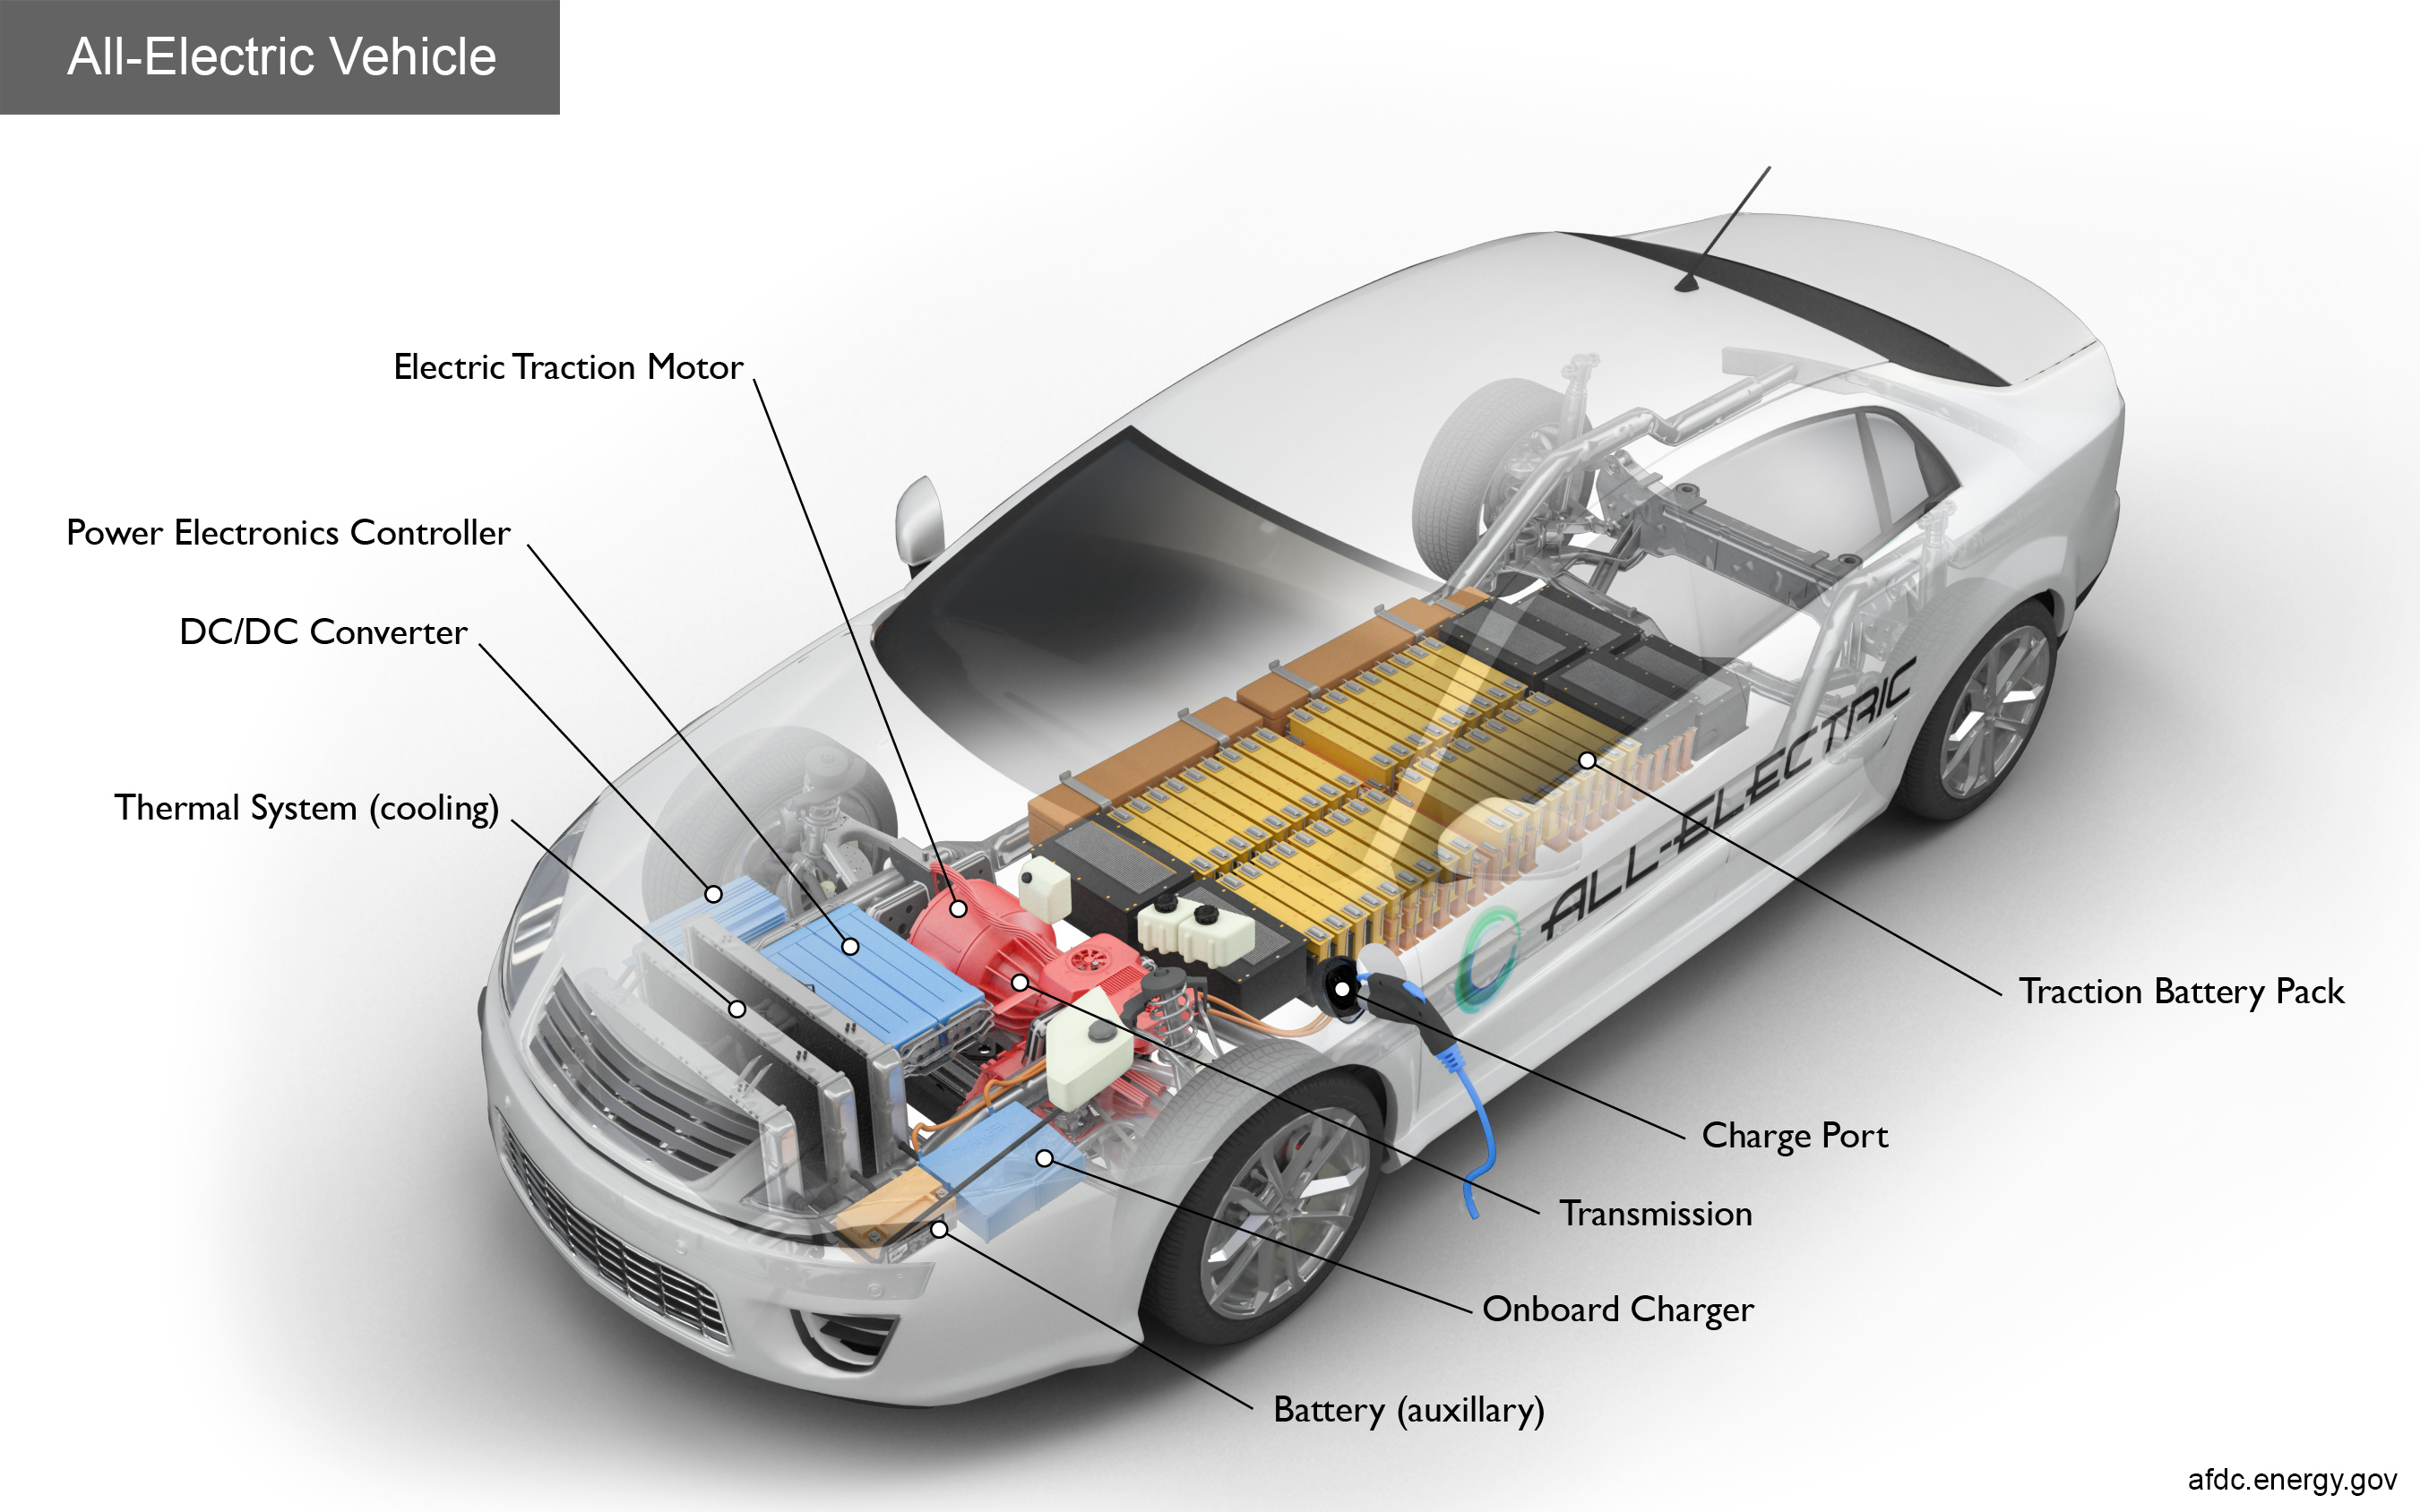

Diagram of an All-Electric Vehicle, credit: [U.S. Department of Energy](https://afdc.energy.gov/vehicles/how-do-all-electric-cars-work)

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

## Types of converters

The importance of DC-to-DC converters lies in their ability to ensure the compatibility of the power source with the electrical load, optimize the use of stored power in batteries, and improve the efficiency and reliability of electronic systems. As technology advances and the demand for portable and renewable energy solutions increases, the role of DC-to-DC converters becomes even more critical in enabling these technologies to perform effectively and efficiently. The operation of these various converters are dependent on a semiconductor switch (MOSFET) and a diode. The input signal for the MOSFET switch will be represented as D, the duty cycle, in this script. The value of the duty cycle is the primary driver behind whether or not the voltage in a converter circuit is increased or decreased. A few types of converters are discussed in the table below:

  **Try**. Use the drop-down menu below to view the different types of converters. Pay attention to the placement of the various components in the circuit. You will notice that the placement of the switch (MOSFET), diode, and inductor affects the circuit's behavior and, thus, conversion.

switchRectifier("No Selection");

 **Exercise 1. **Which of the following voltage changes is a characteristic of a **Boost** Converter? Once you have made your selection, click the **Submit Answers** button below.

exerciseSol1("No Selection");

### Buck converter 

Buck converters are also known as **step down** converters, as in stepping down the voltage from a higher value to a lower value. The basic operation involves two main states (on/off) that are controlled by a MOSFET and a diode using pulse width modulation (PWM). When prolonging battery life in devices is a crucial requirement of a system, buck converters are preferred because of their high efficiency.

** Demonstration**. Let's simulate a buck converter to visualize the behavior of the circuit. The theoretical transfer function of the buck converter is $V_{out} = V_{in}D$. In this example, you will observe that an input voltage of 24 VDC will be stepped down to roughly 12 VDC. Not being exactly equal to 12 VDC is due to the losses characterized in the circuit. The switch is closed when t = 0.035 sec. This activates the converter circuit to step down the voltage at a duty cycle of 50%.

% View half-wave signal
buckFlag = false;

% Run the Simscape model for the half-wave rectifier and store data from
% simulation
if buckFlag
    BuckData = sim("Models/BuckConverter.slx","StopTime","0.08"); %#ok<UNRCH>

    % Plot half-wave rectifier output voltage signal
    t1 = BuckData.ScopeData(:,1);
    v1 = BuckData.ScopeData(:,2);
    v1(:,1) = 24;
    t2 = BuckData.ScopeData(:,1);
    v2 = BuckData.ScopeData(:,2);
    plot(t1,v1,':',t2,v2,'-','LineWidth',2);
    xlabel('Time (sec)'); ylabel('DC Voltage (V)');
    title('Buck Converter Output Voltage, Duty Cycle: 50%  @ t = 0.035 sec');
    legend("Original Signal","Converted Signal");
end

  **Try**. Explore the **buck converter** in Simscape that created the response. Notice that when the switch is open (circuit de-energized), there will be no output voltage across the load. This is evident as there is zero voltage up until 0.035 sec when the switch is energized. When the switch is closed (circuit energized), the flow of current will create a voltage drop across the inductor that opposes the supply voltage, ultimately decreasing the output voltage of the circuit. You can simulate the model using the run icon  .

 

% Open Simscape model for the buck converter 
open_system("Models/BuckConverter.slx")

### Boost converter 

Boost converters are also known as **step up** converters, as in stepping up the voltage from a lower value to a higher value. The basic operation involves two main states (on/off) that are controlled by a MOSFET and a diode using pulse width modulation (PWM). Boost converters, like buck converters, are known to reach high levels of efficiency.

** Demonstration**. Let's simulate a boost converter to visualize the behavior of the circuit. The theoretical transfer function of the boost converter is $V_{out} = V_{in} \frac{1}{1-D}$. In this example, you will observe that an input voltage of 24 VDC will be stepped up to roughly 48 VDC. Not being exactly equal to 48 VDC is due to the losses characterized in the circuit. The switch is open when t = 0.035 sec. This activates the converter circuit to step up the voltage at a duty cycle of 50%.

% View full-wave signal
boostFlag = false;

% Run the Simscape model for the full-wave rectifier and store data from
% simulation
if boostFlag
    BoostData = sim("Models/BoostConverter.slx","StopTime","0.08"); %#ok<UNRCH>

    % Plot half-wave rectifier output voltage signal
    t3 = BoostData.ScopeData(:,1);
    v3 = BoostData.ScopeData(:,2);
    v3(:,1) = 24;
    t4 = BoostData.ScopeData(:,1);
    v4 = BoostData.ScopeData(:,2);
    plot(t3,v3,':',t4,v4,'-','LineWidth',2);
    xlabel('Time (sec)'); ylabel('DC Voltage (V)');
    title('Boost Converter Output Voltage, Duty Cycle: 50%  @ t = 0.035 sec');
    legend("Original Signal","Converted Signal");
end

  **Try**. Explore the **boost converter** in Simscape that created the response. Notice that when the switch is closed (circuit energized), the flow of current will begin to store energy in the inductor, but there will be no output voltage across the load. When the switch is open (circuit de-energized), the discharge current from both the inductor and the voltage source are added together to pass through the diode and across the load, ultimately increasing the output voltage of the circuit. Compared to the buck converter, the boost converter shows a nominal voltage across the load below 0.035 sec. This is due to the configuration of the circuit; where the boost converter's inductor is upstream of the switch and the buck converter's inductor is downstream of the switch.

 

% Open Simscape model for the boost converter 
open_system("Models/BoostConverter.slx")     

### Buck-Boost converter

Buck-Boost converters are a special type of converter that can both **step up and step down **voltage. This means one device can both step up and step down the voltage as needed. The basic operation involves two main states (on/off) that are controlled by a MOSFET and a diode using pulse width modulation (PWM). Buck-Boost converters are highly efficient as they use fewer parts than an individual buck or boost converter. They can also handle input voltages that are above and below the output voltage. One of the disadvantages of the configuration of buck-boost converters is that the output voltage polarity is opposite of the input voltage. For example, if the input voltage is positive, the output voltage will be negative. This behavior occurs because of the PWM switching and placement of the inductor in the circuit. The flow of current in the inductor changes polarity depending on the position of the switch. Buck-boost converters are mostly beneficial in managing power in systems where the input voltage range for system components can vary widely.

** Demonstration**. Let's simulate a buck-boost converter to visualize the behavior of the circuit. **The input voltage for this circuit is positive and, therefore, will have a negative output voltage**. The theoretical transfer function of the buck-boost converter is $|V_{out}| = V_{in} \frac{D}{1-D}$. In this example, you will observe that an input voltage of 24 VDC will be stepped up to roughly -48 VDC and stepped down to roughly -12 VDC, based on the duty cycle input. The switch is closed when t = 0.015 sec with a duty cycle of 67.5%. This activates the converter in boost mode and steps up the voltage. When the switch is open again at t = 0.045 sec, the duty cycle is at 35%. This activates the converter in buck mode and steps down the voltage.

% View full-wave signal
bbFlag = false;

% Run the Simscape model for the full-wave rectifier and store data from
% simulation
if bbFlag
    BBData = sim("Models/BuckBoostConverter.slx","StopTime","0.08"); %#ok<UNRCH>

    % Plot half-wave rectifier output voltage signal
    t5 = BBData.ScopeData(:,1);
    v5 = BBData.ScopeData(:,2);
    v5(:,1) = 24;
    t6 = BBData.ScopeData(:,1);
    v6 = BBData.ScopeData(:,2);
    plot(t5,v5,':',t6,v6,'-','LineWidth',2);
    xlabel('Time (sec)'); ylabel('DC Voltage (V)');
    title('Buck-Boost Converter Output Voltage, Duty Cycle: 67.5%, 35.0%  @ t = 0.015, 0.045 sec');
    legend("Original Signal","Converted Signal");
end

  **Try**. Explore the **buck-boost converter** in Simscape that created the response. Notice that when the switch is open (circuit de-energized, negative polarity), the inductor is connected to the capacitor and load. Meaning that the load only receives energy from the inductor and capacitor (via passage through the diode). When the switch is closed (circuit energized, positive polarity), the input voltage passes through the inductor and begins to charge it. The load only receives energy from the capacitor during this phase. 

 

% Open Simscape model for the buck-boost converter 
open_system("Models/BuckBoostConverter.slx")

 **Note. **There is an additional type of Buck-Boost converter called a [Cuk converter](https://en.wikipedia.org/wiki/%C4%86uk_converter). The purpose of this converter is to reduce the [voltage ripple](https://en.wikipedia.org/wiki/Ripple_(electrical)) by adding an additional capacitor or inductor in the circuit. This type will not be covered in this script.

 **Exercise 2. **You may notice that the signals above have some voltage ripple in them. What is the best way to reduce voltage ripple in a circuit?  Please select all that apply and click the **Submit Answers** button below.

exerciseSol2(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = false);

### Powering sub-components of an electric vehicle

In this next example, we will explore **buck and boost converters** being used in an electric vehicle application. Usually, the input voltage from the EV battery may be lower/higher than the voltage needed to power some of the EV's sub-components, such as the electric traction motor, headlights, and the transmission fluid pump. The EV battery being used in the following example has a capacity of 400 A*hr at 350 VDC. Each sub-component has its own operating voltage required to perform its intended function:

- Electric Traction Motor: 400 V

- Headlights: 12 V

- Transmission Fluid Pump: 12 V

We will observe how an EV battery's charge is affected while powering various sub-components. Launch the model using the button below. In the open model, you will see a few [subsystems](https://www.mathworks.com/help/simulink/subsystems.html) containing the various sub-components.

 

% Open Simscape model for the EV system converter
open_system("Models/EVSystemConverterModel.slx")

 **Exercise 3. ** Design a series of buck and boost converters that allow each subsystem to be powered at their operating voltage given a 350 VDC source. **Utilize the knobs in the model's control panel to adjust the DC-DC converters duty cycle** for the electric traction motor, headlights, and transmission fluid pump. **Once you have adjusted the knobs, simulate the model with the following button.** You can view the output of the DC-DC converters using the [scope](https://www.mathworks.com/help/simulink/slref/scope.html) block labeled "EV Sub-component Voltages and Battery Charge".

 **Note. **If you need to resize the panel for improved model viewing or recover a closed panel, review the help documentation on [managing panel visibility](https://www.mathworks.com/help/simulink/ug/getting-started-with-panels.html#mw_d3ed1cf6-7f4e-4317-b4c2-188d9839cf3a). To quickly open the panel in a separate Simulink window, use the icon   at the top left of the panel window.

 

% Simulate Simscape model for the EV system converter
set_param('EVSystemConverterModel',"StopTime","0.08");
disp("Simulation in progress...")
data = sim("Models/EVSystemConverterModel.slx","StopTime","0.08");
disp("The total simulation time elapsed for exercise 3 is 0.08 seconds.")

Has the desired objective been achieved in the model? Use the button below to check your duty cycle selections. It will be difficult to attain an exact answer for the voltage. If you are within range of the operating voltages (detailed in the following table), you will have achieved the goal of this exercise.

% Calculate the slope of the battery charge signal
cVect = [data.tout,data.Charge];
idx = find(cVect(:,1) >= 0.05,1);
slope = (cVect(end,2)-cVect(idx,2))/(cVect(end,1)-cVect(idx,1));

% Create a table of results for the simulation
printResults(data);

 **Exercise 4.** Imagine you are in an EV driving between two major cities at night. You have a fully charged battery utilizing all the aforementioned sub-components. **At the current duty cycle settings of each DC-DC converter, how long will it take to deplete the charge of the battery?**  The current state of charge of the battery is 100%. The duty cycles you selected in the previous exercise will be used to determine the discharge profile of the battery. Use the slider below to determine how much simulation time (in seconds) it will take to discharge the battery within 1% of empty (0%).

% Slider used to adjust time constant
t =0;

% Using the slope intercept form to solve for charge
b = 100;
charge = (slope*t) + b;
if round(charge,3) == 100
    ...
elseif round(charge,3) <= 0.1 && round(charge,3) >= 0
    disp(['The EV battery will have discharged down to ' num2str(round(charge,3)) '% in ' num2str(round(t/3600,2)) ' hours. This meets the design criteria for the system!'])
elseif round(charge,3) < 0
    warning(['A discharge of ' num2str(round(charge,3)) '% exceeds the limit of the battery capacity.'])
else
    warning(['The EV battery will have discharged down to ' num2str(round(charge,3)) '% in ' num2str(round(t/3600,2)) ' hours.'])
end

 **Note.** The scope block is used to display specific parameters chosen by the user. What if you want to view **all** of the parameters across blocks in a model? The Simulink Data Inspector   tool allows you to view all of your parameters in one place. Once a simulation is run, a `simlog `variable will appear in the workspace. Click the data inspector icon and select the import data button . Select the import button, and you will be able to view all the signals and parameters in the model.

 **Reflect. **We observed how an EV battery discharges energy while utilizing multiple onboard systems. How long would the EV battery take to discharge if we turned off the all sub-components except for the headlights?

## Next Steps

This script covered the fundamentals of converters in power electronics, specifically buck, boost, and buck-boost converters. In later sections of this power electronics module, we will explore other related topics on rectifers and inverters.

## Glossary

MOSFET - Stands for Metal-Oxide-Semiconductor Field-Effect Transistor. It is an electronic device used to switch or amplify voltages in circuits. It is a voltage-controlled device with three terminals: source, gate, and drain. (↑ Return to Text)

Diode -  A semiconductor device that behaves like a one-way valve, allowing current to only flow in one direction. (↑ Return to Text)

Duty Cycle - The ratio of time (pulse) a load or circuit is on compared to the time it is off. (↑ Return to Text)

## Further Exploration

- [Power Electronics Simulation in MATLAB](https://www.mathworks.com/solutions/electrification/power-electronics-simulation.html)

- [Power Electronics Simulation Onramp](https://matlabacademy.mathworks.com/details/power-electronics-simulation-onramp/powerelectronics)

- [MathWorks Examples: Power Converters](https://www.mathworks.com/help/sps/examples.html?category=power-converters&s_tid=CRUX_topnav)

- [Power Electronics with Speedgoat for RCP & HIL](https://www.speedgoat.com/solutions/industries/power-electronics?utm_term=power%20electronics%20matlab&utm_source=google&utm_medium=cpc&device=c&utm_campaign=10278398312&utm_adgroup=135515401899&utm_content=591792460255&gad_source=1&gclid=EAIaIQobChMIy5nB66CEhAMVXl9HAR2KgQSMEAAYASAAEgK42_D_BwE)

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Buck Converter" "Boost Converter" "Buck-Boost Converter"])}
end

if opt == "No Selection"
else
    if opt == "Buck Converter"
        rect = imread("Images/BuckConv.png");
        imshow(rect,Interpolation="bilinear");
    elseif opt == "Boost Converter"
        rect = imread("Images/BoostConv.png");
        imshow(rect,Interpolation="bilinear");
    elseif opt == "Buck-Boost Converter"
        rect = imread("Images/BBConv.png");
        imshow(rect,Interpolation="bilinear");
    end
end
end

function exerciseSol1(opts)
    % Provides solution for Exercise 1
    arguments
        opts (1,1) string {mustBeMember(opts,["No Selection" "12V <--> 24V" "12V --> 12V" "24V --> 12V" "12V --> 24V"])} = "No Selection"
    end

    switch (opts)
        case "No Selection"
            disp("Please select one of the options in the drop down menu.")
        case "12V <--> 24V"
            warning("Converting back and forth between high and low voltage is a characteristic of a buck-boost converter.")
        case "12V --> 12V"
            warning("The voltage is constant and no conversion is happening in this scenario. It is not representative of any of the converters being discussed in this script.")
        case "24V --> 12V"
            warning("The input voltage is decreasing in this scenario. This is a characteristic of a buck converter.")
        case "12V --> 24V"
            disp("Correct! The input voltage increasing to a higher output voltage is a characteristic of a boost converter.")
    end
end

function exerciseSol2(subs)
    % Provides solution for Exercise 2
    arguments
        subs.A (1,1) logical
        subs.B (1,1) logical
        subs.C (1,1) logical
        subs.D (1,1) logical
    end

    if ~any([subs.A subs.B subs.C subs.D])
        disp("Please select all that apply!")
    elseif [subs.B subs.C] & ~[subs.A subs.D] %#ok<AND2,BDSCA>
        disp("Correct! Both capacitors and inductors can reduce voltage ripple in a circuit.")
    elseif [subs.A subs.B] & ~[subs.C subs.D] | [subs.A subs.C] & ~[subs.B subs.D] | [subs.A subs.D] & ~[subs.B subs.C] | [subs.B subs.D] & ~[subs.A subs.C] | [subs.C subs.D] & ~[subs.A subs.B] %#ok<AND2,OR2,BDSCA>
        warning("Incorrect. You have not selected all the components that can reduce voltage ripple.")
    elseif subs.A
        warning("Adding a resistor to a circuit will reduce the current flowing through it. It won't reduce voltage ripple.")
    elseif subs.B
        warning("Adding a capacitor to a circuit will help to reduce voltage ripple because it blocks a change in current as it charges. However, it is not the only component that has this characteristic.")
    elseif subs.C
        warning("Adding an inductor to a circuit will help to reduce voltage ripple because it opposes a change in current. However, it is not the only component that has this characteristic.")
    elseif subs.D
        warning("Adding a transformer to a circuit will either step up or step down voltage. It won't reduce voltage ripple.")
    end
end

function printResults(data)
    % Code for creating a table to display values of simulation results
    % Find the final voltage of each subsystem and the total voltage
    vf1 = round(data.V_ETM(end),2);
    vf2 = round(data.V_Head(end),2);
    vf3 = round(data.V_TFP(end),2);
    
    % Verify subsystem voltages are within range of actual operating voltages
    vr1 = 400*0.02; % 2% of actuals
    vr2 = 12*0.1; % 10% of actuals
    or1 = vf1 >= 400 - vr1 & vf1 <= 400 + vr1;
    or2 = vf2 >= 12 - vr2 & vf2 <= 12 + vr2;
    or3 = vf3 >= 12 - vr2 & vf3 <= 12 + vr2;
    
    if  or1 == 1
        orCheck1 = "Yes";
    else
        orCheck1 = "No";
    end

    if  or2 == 1
        orCheck2 = "Yes";
    else
        orCheck2 = "No";
    end

    if  or3 == 1
        orCheck3 = "Yes";
    else
        orCheck3 = "No";
    end
    
    % Create variable for storing current duty cycle
    dc1 = round(data.DC_ETM(end),4);
    dc2 = round(data.DC_Head(end),4);
    dc3 = round(data.DC_TFP(end),4);
    
    % Display results of voltage check
    format shortG
    % if vCheck == 1 && orCheck == 1
        % disp('Yes! The duty cycles chosen provide a balanced usage of the input voltage to power each of the subsystems in the smartphone.')
    Subsystem = {"Electric Traction Motor";"Headlights";"Transmission Fluid Pump"};
    DutyCycle = string([dc1;dc2;dc3]*100);
    Voltage = string([vf1;vf2;vf3]);
    OperatingVoltage = ["400 V";"12 V";"12 V"];
    WithinRange = [orCheck1;orCheck2;orCheck3];
    Results = table(Subsystem,OperatingVoltage,DutyCycle,Voltage,WithinRange) %#ok<NASGU,NOPRT>
    % else % vCheck == 0 && orCheck == 0
    %     warning('No. The duty cycles you have chosen did not produce a system that meets the 9V system requirement within the respective subsystem operating ranges. Please try another combination and run the simulation again with the button above.')
    %     Subsystem = {'Battery';'Camera';'Accelerometer'};
    %     DutyCycle = [dc1;dc2;dc3];
    %     Voltage = [vf1;vf2;vf3];
    %     OperatingRange = {'3.7 - 4.2 V';'1.8 -  3.3 V';'1.8 -  3.3 V'};
    %     SumVolts = [NaN;vTotal;NaN];
    %     Results = table(DutyCycle,Voltage,SumVolts,OperatingRange,'RowNames',Subsystem) %#ok<NASGU,NOPRT>
    % end
end